% 根据优化范围内的构型微调量和可操作度计算目标函数值
% TarFuncVau_OptiRang
%% 优化区间内的相对可操作度和相对构型变化量
% 生成关节构型
Num_ConfOpti = 75056;
deg_joint1 = zeros(Num_ConfOpti,1);
deg_joint2 = zeros(Num_ConfOpti,1);
deg_joint3 = zeros(Num_ConfOpti,1);
deg_joint4 = zeros(Num_ConfOpti,1);
deg_joint5 = zeros(Num_ConfOpti,1);
deg_joint6 = zeros(Num_ConfOpti,1);
deg_joint7 = zeros(Num_ConfOpti,1);

rng(66);
for ii = 1:Num_ConfOpti         % 关节1/3/5/7随机取值
    deg_joint1(ii) = -180 + 360 * rand;
    deg_joint3(ii) = -70 + 142 * rand;
    deg_joint5(ii) = -75 + 155 * rand;
    deg_joint7(ii) = -180 + 360 * rand;   % 关节7的角度值为±50 randi([0,1])
end
for ii = 1:Num_ConfOpti/2       % 关节2/4/6随机取值
    deg_joint2(ii) = -140 + 89 * rand;
    deg_joint2(Num_ConfOpti/2 + ii) = 51 + 89 * rand;
    deg_joint4(ii) = -95 + 27 * rand;
    deg_joint4(Num_ConfOpti/2 + ii) = 68 + 27 * rand;
    deg_joint6(ii) = -120 + 69 * rand;
    deg_joint6(Num_ConfOpti/2 + ii) = 51 + 69 * rand;
end
Deg_alljoint = [deg_joint1 deg_joint2 deg_joint3 deg_joint4 deg_joint5 deg_joint6 deg_joint7];
Confi_Robot = Deg_alljoint;
% ConfiNum_First = size(Confi_Robot,1);

Opti_Mani = zeros(Num_ConfOpti,1);
Opti_RelaMani = zeros(Num_ConfOpti,1);
for ii = 1:Num_ConfOpti
    Theta_deg = Deg_alljoint(ii,:);
    Theta_rad = Theta_deg * pi / 180;       % 将角度单位从°转化为rad
    % 可操作度计算
    Jaco_End = JoiAngToJacMatEnd(Theta_rad);
    Trans_JacoEnd = Jaco_End.';
    Det_JacoEnd = det(Jaco_End * Trans_JacoEnd);
    Opti_Mani(ii) = sqrt(Det_JacoEnd);
    Opti_RelaMani(ii) = Opti_Mani(ii) / 30;       % 计算相对可操作度
end
% 计算相对构型变化量
load('ConfiAndVari_OptiRang.mat');        % 加载优化范围内的构型变化量
Opti_RelaConfiVari = zeros(Num_ConfOpti,1);
for ii = 1 : Num_ConfOpti      % 求解相对构型微调量
    media_confivari =  -0.03 * ConfiAndVari_OptiRang(ii, 8);
    Opti_RelaConfiVari(ii) = 1.8 * exp(media_confivari);
end

Opti_TarFunc = zeros(Num_ConfOpti,1);
for ii = 1 : Num_ConfOpti
    Opti_TarFunc(ii) = 0.7 * Opti_RelaMani(ii) + 0.3 * Opti_RelaConfiVari(ii);
end
[Min_OptiRelaMani,Max_OptiRelaMani] = bounds(Opti_RelaMani)

Min_OptiRelaMani = 0.4074

Max_OptiRelaMani = 0.8955

Mea_OptiRelaMani = mean(Opti_RelaMani)

Mea_OptiRelaMani = 0.7157

[Min_OptiRelaConfiVari,Max_OptiRelaConfiVari] = bounds(Opti_RelaConfiVari)

Min_OptiRelaConfiVari = 0.4635

Max_OptiRelaConfiVari = 0.9740

Mea_OptiRelaConfiVari = mean(Opti_RelaConfiVari)

Mea_OptiRelaConfiVari = 0.7112

% 关节极限范围内的相对可操作度和相对构型变化量
load('All_Vari_Sec.mat');       % 包含操作构型和构型变化量的数组
load('All_RelaConfiVari.mat');  % 加载相对构型变化量

Num_Confi = size(All_Vari_Sec,1);
All_Mani = zeros(Num_Confi,1);
All_RelaMani = zeros(Num_Confi,1);
for jj = 1 : Num_Confi
    Theta_degree = All_Vari_Sec(jj,1:7);
    Theta_rad = Theta_degree * pi / 180;
    Jaco_End = JoiAngToJacMatEnd(Theta_rad);
    Trans_JacoEnd = Jaco_End.';
    Det_JacoEnd = det(Jaco_End * Trans_JacoEnd);
    All_Mani(jj) = sqrt(Det_JacoEnd);
    All_RelaMani(jj) = All_Mani(jj) / 30;   
end
[Min_AllRelaMani,Max_AllRelaMani] = bounds(All_RelaMani)

Min_AllRelaMani = 1.8802e-04

Max_AllRelaMani = 0.8805

Mea_AllRelaMani = mean(All_RelaMani)

Mea_AllRelaMani = 0.2791

[Min_AllRelaConfiVari,Max_AllRelaConfiVari] = bounds(All_RelaConfiVari)

Min_AllRelaConfiVari = 1.8461e-05

Max_AllRelaConfiVari = 0.9931

Mea_AllRelaConfiVari = mean(All_RelaConfiVari)

Mea_AllRelaConfiVari = 0.3934


All_TarFunc = zeros(Num_Confi,1);
for ii = 1 : Num_Confi
    All_TarFunc(ii) = 0.7 * All_RelaMani(ii) + 0.3 * All_RelaConfiVari(ii);
end

[Max_RelaMan,II_RelaMan] = max(All_RelaMani,[],1)

Max_RelaMan = 0.8805

II_RelaMan = 16114

[Max_RelaVari,II_RelaVari] = max(All_RelaConfiVari,[],1)

Max_RelaVari = 0.9931

II_RelaVari = 34834

[Min_AllTarFunc,Max_AllTarFunc] = bounds(All_TarFunc)

Min_AllTarFunc = 1.5173e-04

Max_AllTarFunc = 0.8393

Mea_AllTarFunc = mean(All_TarFunc)

Mea_AllTarFunc = 0.3134

[Min_OptiTarFunc,Max_OptiTarFunc] = bounds(Opti_TarFunc)

Min_OptiTarFunc = 0.4749

Max_OptiTarFunc = 0.8839

Mea_OptiTarFunc = mean(Opti_TarFunc)

Mea_OptiTarFunc = 0.7143

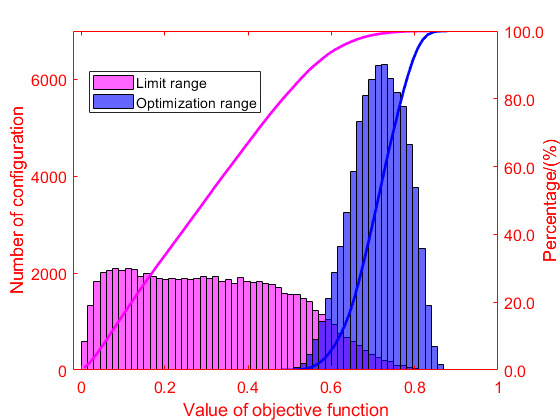


% 绘制目标函数值的对比
figure;
yyaxis left;
HH_AllTarFunc = histogram(All_TarFunc);        % All_RelaConfiVari
HH_AllTarFunc.BinWidth = 0.015;
HH_AllTarFunc.FaceColor = [1.00,0.00,1.00];
hold on;
HH_OptiTarFunc = histogram(Opti_TarFunc);
HH_OptiTarFunc.BinWidth = 0.015;
HH_OptiTarFunc.FaceColor = [0.00,0.00,1.00];
hold off;

yticks(0:2000:8000);
xlim([-0.02 1.0]);
xticks(0:0.2:1.0);
ylabel('Number of configuration',"FontSize",13);      % ,"FontSize",13
set(gca,'YColor',[1.00,0.00,0.00]);
yyaxis right;
[counts_AllTarFunc,centers_AllTarFunc] = hist(All_TarFunc,64);
frequency_AllTarFunc = counts_AllTarFunc / sum(counts_AllTarFunc);
CumFrequency_AllTarFunc = cumsum(frequency_AllTarFunc,2);
figdis_AllTarFunc = plot(centers_AllTarFunc,100 * CumFrequency_AllTarFunc);
figdis_AllTarFunc.Color = [1.00,0.00,1.00];
figdis_AllTarFunc.LineWidth = 2;
hold on;
[counts_OptiTarFunc,centers_OptiTarFunc] = hist(Opti_TarFunc,35);
frequency_OptiTarFunc = counts_OptiTarFunc / sum(counts_OptiTarFunc);
CumFrequency_OptiTarFunc = cumsum(frequency_OptiTarFunc,2);
figdis_OptiTarFunc = plot(centers_OptiTarFunc,100 * CumFrequency_OptiTarFunc,'LineStyle',"-");
figdis_OptiTarFunc.Color = [0.00,0.00,1.00];
figdis_OptiTarFunc.LineWidth = 2;
hold off;
ylim([0 100]);
yticks(0:20:100);
legend('Limit range','Optimization range','Position',[0.172380949639139,0.731726189431697,0.281071433101381,0.098333335422334]);
xlabel('Value of objective function','VerticalAlignment',"top","FontSize",13);
ylabel ('Percentage/(%)',"VerticalAlignment","middle","FontSize",13);
ytickformat('%.1f');     % 设置百分数小数点后的显示位数
set(gca,'XColor',[1.00,0.00,0.00],'YColor',[1.00,0.00,0.00],'FontSize',12);

function Jaco_end = JoiAngToJacMatEnd(Theta)
%%   根据输入的关节角度计算雅克比矩阵
%   输入量为包含7个关节角度的数组，单位为rad；
%   输出量为使用旋量法以末端坐标系为参考的雅可比矩阵；
%   使用旋量法求解得到的雅可比矩阵前三列是角速度，后三列是线速度，与DH法的相反；
%% 单位转化
% Theta_rad = Theta * pi /180;
Theta_rad = Theta;
%% 机械臂关节常量定义





%% 关节角度赋值
theta1 = Theta_rad(1);
theta2 = Theta_rad(2);
theta3 = Theta_rad(3);
theta4 = Theta_rad(4);
theta5 = Theta_rad(5);
theta6 = Theta_rad(6);
theta7 = Theta_rad(7);
%% 求解公式
Je_B1 = [cos(theta2)*cos(theta6) - cos(theta3 + theta4 + theta5)*sin(theta2)*sin(theta6);
        sin(theta2)*(cos(theta3)*(cos(theta4)*(sin(theta5)*sin(theta7) - cos(theta5)*cos(theta6)*cos(theta7)) + sin(theta4)*(cos(theta5)*sin(theta7) + cos(theta6)*cos(theta7)*sin(theta5))) + sin(theta3)*(cos(theta4)*(cos(theta5)*sin(theta7) + cos(theta6)*cos(theta7)*sin(theta5)) - sin(theta4)*(sin(theta5)*sin(theta7) - cos(theta5)*cos(theta6)*cos(theta7)))) - cos(theta2)*cos(theta7)*sin(theta6);
        sin(theta2)*(cos(theta3)*(cos(theta4)*(cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*sin(theta7)) + sin(theta4)*(cos(theta5)*cos(theta7) - cos(theta6)*sin(theta5)*sin(theta7))) + sin(theta3)*(cos(theta4)*(cos(theta5)*cos(theta7) - cos(theta6)*sin(theta5)*sin(theta7)) - sin(theta4)*(cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*sin(theta7)))) + cos(theta2)*sin(theta6)*sin(theta7);
        a3N*cos(theta2)*sin(theta4)*sin(theta5)*sin(theta6) - a7N*cos(theta2)*sin(theta6) - a3N*cos(theta3)*cos(theta6)*sin(theta2) - a5N*cos(theta2)*cos(theta5)*sin(theta6) - a3N*cos(theta2)*cos(theta4)*cos(theta5)*sin(theta6) - a5N*cos(theta3)*cos(theta4)*cos(theta6)*sin(theta2) - a1N*cos(theta6)*sin(theta2) + a5N*cos(theta6)*sin(theta2)*sin(theta3)*sin(theta4) - a1N*cos(theta2)*cos(theta3)*cos(theta4)*cos(theta5)*sin(theta6) - a7N*cos(theta3)*cos(theta4)*cos(theta5)*cos(theta6)*sin(theta2) + a1N*cos(theta2)*cos(theta3)*sin(theta4)*sin(theta5)*sin(theta6) + a1N*cos(theta2)*cos(theta4)*sin(theta3)*sin(theta5)*sin(theta6) + a1N*cos(theta2)*cos(theta5)*sin(theta3)*sin(theta4)*sin(theta6) + a2N*cos(theta3)*cos(theta4)*sin(theta2)*sin(theta5)*sin(theta6) + a2N*cos(theta3)*cos(theta5)*sin(theta2)*sin(theta4)*sin(theta6) + a2N*cos(theta4)*cos(theta5)*sin(theta2)*sin(theta3)*sin(theta6) + a4N*cos(theta3)*cos(theta4)*sin(theta2)*sin(theta5)*sin(theta6) + a4N*cos(theta3)*cos(theta5)*sin(theta2)*sin(theta4)*sin(theta6) + a4N*cos(theta4)*cos(theta5)*sin(theta2)*sin(theta3)*sin(theta6) + a6N*cos(theta3)*cos(theta4)*sin(theta2)*sin(theta5)*sin(theta6) + a6N*cos(theta3)*cos(theta5)*sin(theta2)*sin(theta4)*sin(theta6) + a6N*cos(theta4)*cos(theta5)*sin(theta2)*sin(theta3)*sin(theta6) + a7N*cos(theta3)*cos(theta6)*sin(theta2)*sin(theta4)*sin(theta5) + a7N*cos(theta4)*cos(theta6)*sin(theta2)*sin(theta3)*sin(theta5) + a7N*cos(theta5)*cos(theta6)*sin(theta2)*sin(theta3)*sin(theta4) - a2N*sin(theta2)*sin(theta3)*sin(theta4)*sin(theta5)*sin(theta6) - a4N*sin(theta2)*sin(theta3)*sin(theta4)*sin(theta5)*sin(theta6) - a6N*sin(theta2)*sin(theta3)*sin(theta4)*sin(theta5)*sin(theta6);
        (cos(theta2)*(cos(theta3)*(cos(theta4)*(sin(theta5)*sin(theta7) - cos(theta5)*cos(theta6)*cos(theta7)) + sin(theta4)*(cos(theta5)*sin(theta7) + cos(theta6)*cos(theta7)*sin(theta5))) + sin(theta3)*(cos(theta4)*cos(theta5)*sin(theta7) - sin(theta4)*sin(theta5)*sin(theta7) + cos(theta4)*cos(theta6)*cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*cos(theta7)*sin(theta4))) + cos(theta7)*sin(theta2)*sin(theta6))*(a1N + a3N + a5N + a7N) + (cos(theta2)*cos(theta6) - cos(theta3 + theta4 + theta5)*sin(theta2)*sin(theta6))*((a5N + a7N)*(cos(theta4) - 1)*(cos(theta5)*cos(theta7) - cos(theta6)*sin(theta5)*sin(theta7)) + a8N*sin(theta6)*sin(theta7) - sin(theta3)*(cos(theta4)*(cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*sin(theta7)) + sin(theta4)*(cos(theta5)*cos(theta7) - cos(theta6)*sin(theta5)*sin(theta7)))*(a3N + a5N + a7N) + sin(theta2)*(cos(theta3)*(cos(theta4)*(cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*sin(theta7)) + sin(theta4)*(cos(theta5)*cos(theta7) - cos(theta6)*sin(theta5)*sin(theta7))) + sin(theta3)*(cos(theta4)*(cos(theta5)*cos(theta7) - cos(theta6)*sin(theta5)*sin(theta7)) - sin(theta4)*(cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*sin(theta7))))*(a2N + a4N + a6N + a8N) + a7N*cos(theta7)*(cos(theta5) - 1) - sin(theta4)*(a5N + a7N)*(cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*sin(theta7)) + (cos(theta3) - 1)*(cos(theta4)*(cos(theta5)*cos(theta7) - cos(theta6)*sin(theta5)*sin(theta7)) - sin(theta4)*(cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*sin(theta7)))*(a3N + a5N + a7N) + sin(theta6)*sin(theta7)*(cos(theta2) - 1)*(a2N + a4N + a6N + a8N) - a7N*cos(theta6)*sin(theta5)*sin(theta7)) - (sin(theta2)*(cos(theta3)*(cos(theta4)*(cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*sin(theta7)) + sin(theta4)*(cos(theta5)*cos(theta7) - cos(theta6)*sin(theta5)*sin(theta7))) + sin(theta3)*(cos(theta4)*(cos(theta5)*cos(theta7) - cos(theta6)*sin(theta5)*sin(theta7)) - sin(theta4)*(cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*sin(theta7)))) + cos(theta2)*sin(theta6)*sin(theta7))*(a8N*(cos(theta6) - 1) + cos(theta6)*(cos(theta2) - 1)*(a2N + a4N + a6N + a8N) + a7N*sin(theta5)*sin(theta6) + cos(theta5)*sin(theta4)*sin(theta6)*(a5N + a7N) - cos(theta3 + theta4 + theta5)*sin(theta2)*sin(theta6)*(a2N + a4N + a6N + a8N) + cos(theta4 + theta5)*sin(theta3)*sin(theta6)*(a3N + a5N + a7N) + sin(theta5)*sin(theta6)*(a5N + a7N)*(cos(theta4) - 1) + sin(theta4 + theta5)*sin(theta6)*(cos(theta3) - 1)*(a3N + a5N + a7N));
        (cos(theta2)*(cos(theta3)*(cos(theta4)*(cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*sin(theta7)) + sin(theta4)*(cos(theta5)*cos(theta7) - cos(theta6)*sin(theta5)*sin(theta7))) + sin(theta3)*(cos(theta4)*(cos(theta5)*cos(theta7) - cos(theta6)*sin(theta5)*sin(theta7)) - sin(theta4)*(cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*sin(theta7)))) - sin(theta2)*sin(theta6)*sin(theta7))*(a1N + a3N + a5N + a7N) - (cos(theta2)*cos(theta6) - cos(theta3 + theta4 + theta5)*sin(theta2)*sin(theta6))*((cos(theta3) - 1)*(a3N + a5N + a7N)*(cos(theta4)*cos(theta5)*sin(theta7) - sin(theta4)*sin(theta5)*sin(theta7) + cos(theta4)*cos(theta6)*cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*cos(theta7)*sin(theta4)) + (a5N + a7N)*(cos(theta4) - 1)*(cos(theta5)*sin(theta7) + cos(theta6)*cos(theta7)*sin(theta5)) - a8N*cos(theta7)*sin(theta6) - sin(theta3)*(cos(theta4)*(sin(theta5)*sin(theta7) - cos(theta5)*cos(theta6)*cos(theta7)) + sin(theta4)*(cos(theta5)*sin(theta7) + cos(theta6)*cos(theta7)*sin(theta5)))*(a3N + a5N + a7N) + sin(theta2)*(cos(theta3)*(cos(theta4)*(sin(theta5)*sin(theta7) - cos(theta5)*cos(theta6)*cos(theta7)) + sin(theta4)*(cos(theta5)*sin(theta7) + cos(theta6)*cos(theta7)*sin(theta5))) + sin(theta3)*(cos(theta4)*cos(theta5)*sin(theta7) - sin(theta4)*sin(theta5)*sin(theta7) + cos(theta4)*cos(theta6)*cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*cos(theta7)*sin(theta4)))*(a2N + a4N + a6N + a8N) - sin(theta4)*(a5N + a7N)*(sin(theta5)*sin(theta7) - cos(theta5)*cos(theta6)*cos(theta7)) + a7N*sin(theta7)*(cos(theta5) - 1) - cos(theta7)*sin(theta6)*(cos(theta2) - 1)*(a2N + a4N + a6N + a8N) + a7N*cos(theta6)*cos(theta7)*sin(theta5)) + (sin(theta2)*(cos(theta3)*(cos(theta4)*(sin(theta5)*sin(theta7) - cos(theta5)*cos(theta6)*cos(theta7)) + sin(theta4)*(cos(theta5)*sin(theta7) + cos(theta6)*cos(theta7)*sin(theta5))) + sin(theta3)*(cos(theta4)*cos(theta5)*sin(theta7) - sin(theta4)*sin(theta5)*sin(theta7) + cos(theta4)*cos(theta6)*cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*cos(theta7)*sin(theta4))) - cos(theta2)*cos(theta7)*sin(theta6))*(a8N*(cos(theta6) - 1) + cos(theta6)*(cos(theta2) - 1)*(a2N + a4N + a6N + a8N) + a7N*sin(theta5)*sin(theta6) + cos(theta5)*sin(theta4)*sin(theta6)*(a5N + a7N) - cos(theta3 + theta4 + theta5)*sin(theta2)*sin(theta6)*(a2N + a4N + a6N + a8N) + cos(theta4 + theta5)*sin(theta3)*sin(theta6)*(a3N + a5N + a7N) + sin(theta5)*sin(theta6)*(a5N + a7N)*(cos(theta4) - 1) + sin(theta4 + theta5)*sin(theta6)*(cos(theta3) - 1)*(a3N + a5N + a7N))];
Je_B2 = [sin(theta3 + theta4 + theta5)*sin(theta6);
        cos(theta3)*(cos(theta4)*(cos(theta5)*sin(theta7) + cos(theta6)*cos(theta7)*sin(theta5)) - sin(theta4)*(sin(theta5)*sin(theta7) - cos(theta5)*cos(theta6)*cos(theta7))) - sin(theta3)*(cos(theta4)*(sin(theta5)*sin(theta7) - cos(theta5)*cos(theta6)*cos(theta7)) + sin(theta4)*(cos(theta5)*sin(theta7) + cos(theta6)*cos(theta7)*sin(theta5)));
        cos(theta3)*(cos(theta4)*(cos(theta5)*cos(theta7) - cos(theta6)*sin(theta5)*sin(theta7)) - sin(theta4)*(cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*sin(theta7))) - sin(theta3)*(cos(theta4)*(cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*sin(theta7)) + sin(theta4)*(cos(theta5)*cos(theta7) - cos(theta6)*sin(theta5)*sin(theta7)));
        (a5N*sin(theta3 + theta4 - theta6))/2 + (a2N*sin(theta3 + theta4 + theta5 + theta6))/2 + (a4N*sin(theta3 + theta4 + theta5 + theta6))/2 + (a6N*sin(theta3 + theta4 + theta5 + theta6))/2 + (a7N*sin(theta3 + theta4 + theta5 + theta6))/2 + (a3N*sin(theta3 + theta6))/2 - (a2N*sin(theta3 + theta4 + theta5 - theta6))/2 - (a4N*sin(theta3 + theta4 + theta5 - theta6))/2 - (a6N*sin(theta3 + theta4 + theta5 - theta6))/2 + (a7N*sin(theta3 + theta4 + theta5 - theta6))/2 + (a3N*sin(theta3 - theta6))/2 + (a5N*sin(theta3 + theta4 + theta6))/2;
        sin(theta3 + theta4 + theta5)*sin(theta6)*((a5N + a7N)*(cos(theta4) - 1)*(cos(theta5)*cos(theta7) - cos(theta6)*sin(theta5)*sin(theta7)) + a8N*sin(theta6)*sin(theta7) - sin(theta3)*(cos(theta4)*(cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*sin(theta7)) + sin(theta4)*(cos(theta5)*cos(theta7) - cos(theta6)*sin(theta5)*sin(theta7)))*(a3N + a5N + a7N) + a7N*cos(theta7)*(cos(theta5) - 1) - sin(theta4)*(a5N + a7N)*(cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*sin(theta7)) + (cos(theta3) - 1)*(cos(theta4)*(cos(theta5)*cos(theta7) - cos(theta6)*sin(theta5)*sin(theta7)) - sin(theta4)*(cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*sin(theta7)))*(a3N + a5N + a7N) - a7N*cos(theta6)*sin(theta5)*sin(theta7)) - (cos(theta3)*(cos(theta4)*(sin(theta5)*sin(theta7) - cos(theta5)*cos(theta6)*cos(theta7)) + sin(theta4)*(cos(theta5)*sin(theta7) + cos(theta6)*cos(theta7)*sin(theta5))) + sin(theta3)*(cos(theta4)*cos(theta5)*sin(theta7) - sin(theta4)*sin(theta5)*sin(theta7) + cos(theta4)*cos(theta6)*cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*cos(theta7)*sin(theta4)))*(a2N + a4N + a6N + a8N) - (cos(theta3)*(cos(theta4)*(cos(theta5)*cos(theta7) - cos(theta6)*sin(theta5)*sin(theta7)) - sin(theta4)*(cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*sin(theta7))) - sin(theta3)*(cos(theta4)*(cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*sin(theta7)) + sin(theta4)*(cos(theta5)*cos(theta7) - cos(theta6)*sin(theta5)*sin(theta7))))*(a8N*(cos(theta6) - 1) + a7N*sin(theta5)*sin(theta6) + cos(theta5)*sin(theta4)*sin(theta6)*(a5N + a7N) + cos(theta4 + theta5)*sin(theta3)*sin(theta6)*(a3N + a5N + a7N) + sin(theta5)*sin(theta6)*(a5N + a7N)*(cos(theta4) - 1) + sin(theta4 + theta5)*sin(theta6)*(cos(theta3) - 1)*(a3N + a5N + a7N));
        (cos(theta3)*(cos(theta4)*(cos(theta5)*sin(theta7) + cos(theta6)*cos(theta7)*sin(theta5)) - sin(theta4)*(sin(theta5)*sin(theta7) - cos(theta5)*cos(theta6)*cos(theta7))) - sin(theta3)*(cos(theta4)*(sin(theta5)*sin(theta7) - cos(theta5)*cos(theta6)*cos(theta7)) + sin(theta4)*(cos(theta5)*sin(theta7) + cos(theta6)*cos(theta7)*sin(theta5))))*(a8N*(cos(theta6) - 1) - sin(theta3)*(sin(theta4)*sin(theta5)*sin(theta6) - cos(theta4)*cos(theta5)*sin(theta6))*(a3N + a5N + a7N) + (cos(theta3) - 1)*(cos(theta4)*sin(theta5)*sin(theta6) + cos(theta5)*sin(theta4)*sin(theta6))*(a3N + a5N + a7N) + a7N*sin(theta5)*sin(theta6) + cos(theta5)*sin(theta4)*sin(theta6)*(a5N + a7N) + sin(theta5)*sin(theta6)*(a5N + a7N)*(cos(theta4) - 1)) - (cos(theta3)*(cos(theta4)*sin(theta5)*sin(theta6) + cos(theta5)*sin(theta4)*sin(theta6)) - sin(theta3)*(sin(theta4)*sin(theta5)*sin(theta6) - cos(theta4)*cos(theta5)*sin(theta6)))*((a5N + a7N)*(cos(theta4) - 1)*(cos(theta5)*sin(theta7) + cos(theta6)*cos(theta7)*sin(theta5)) - a8N*cos(theta7)*sin(theta6) - sin(theta3)*(cos(theta4)*(sin(theta5)*sin(theta7) - cos(theta5)*cos(theta6)*cos(theta7)) + sin(theta4)*(cos(theta5)*sin(theta7) + cos(theta6)*cos(theta7)*sin(theta5)))*(a3N + a5N + a7N) - sin(theta4)*(a5N + a7N)*(sin(theta5)*sin(theta7) - cos(theta5)*cos(theta6)*cos(theta7)) + a7N*sin(theta7)*(cos(theta5) - 1) + (cos(theta3) - 1)*(cos(theta4)*(cos(theta5)*sin(theta7) + cos(theta6)*cos(theta7)*sin(theta5)) - sin(theta4)*(sin(theta5)*sin(theta7) - cos(theta5)*cos(theta6)*cos(theta7)))*(a3N + a5N + a7N) + a7N*cos(theta6)*cos(theta7)*sin(theta5)) - (cos(theta3)*(cos(theta4)*(cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*sin(theta7)) + sin(theta4)*(cos(theta5)*cos(theta7) - cos(theta6)*sin(theta5)*sin(theta7))) + sin(theta3)*(cos(theta4)*(cos(theta5)*cos(theta7) - cos(theta6)*sin(theta5)*sin(theta7)) - sin(theta4)*(cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*sin(theta7))))*(a2N + a4N + a6N + a8N)];
Je_B3 = [cos(theta6);
        -cos(theta7)*sin(theta6);
        sin(theta6)*sin(theta7);
        -sin(theta6)*(a7N + a3N*cos(theta4 + theta5) + a5N*cos(theta5));
        cos(theta6)*((a5N + a7N)*(cos(theta4) - 1)*(cos(theta5)*cos(theta7) - cos(theta6)*sin(theta5)*sin(theta7)) + a8N*sin(theta6)*sin(theta7) + a7N*cos(theta7)*(cos(theta5) - 1) - sin(theta4)*(a5N + a7N)*(cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*sin(theta7)) - a7N*cos(theta6)*sin(theta5)*sin(theta7)) + (cos(theta4)*(sin(theta5)*sin(theta7) - cos(theta5)*cos(theta6)*cos(theta7)) + sin(theta4)*(cos(theta5)*sin(theta7) + cos(theta6)*cos(theta7)*sin(theta5)))*(a3N + a5N + a7N) - sin(theta6)*sin(theta7)*(a8N*(cos(theta6) - 1) + a7N*sin(theta5)*sin(theta6) + cos(theta5)*sin(theta4)*sin(theta6)*(a5N + a7N) + sin(theta5)*sin(theta6)*(a5N + a7N)*(cos(theta4) - 1));
        (cos(theta4)*(cos(theta7)*sin(theta5) + cos(theta5)*cos(theta6)*sin(theta7)) + sin(theta4)*(cos(theta5)*cos(theta7) - cos(theta6)*sin(theta5)*sin(theta7)))*(a3N + a5N + a7N) - cos(theta6)*((a5N + a7N)*(cos(theta4) - 1)*(cos(theta5)*sin(theta7) + cos(theta6)*cos(theta7)*sin(theta5)) - a8N*cos(theta7)*sin(theta6) - sin(theta4)*(a5N + a7N)*(sin(theta5)*sin(theta7) - cos(theta5)*cos(theta6)*cos(theta7)) + a7N*sin(theta7)*(cos(theta5) - 1) + a7N*cos(theta6)*cos(theta7)*sin(theta5)) - cos(theta7)*sin(theta6)*(a8N*(cos(theta6) - 1) + a7N*sin(theta5)*sin(theta6) + cos(theta5)*sin(theta4)*sin(theta6)*(a5N + a7N) + sin(theta5)*sin(theta6)*(a5N + a7N)*(cos(theta4) - 1))];
Je_B4 = [cos(theta6);
        -cos(theta7)*sin(theta6);
        sin(theta6)*sin(theta7);
        -sin(theta6)*(a7N + a5N*cos(theta5));
        a5N*sin(theta5)*sin(theta7) - a7N*cos(theta6)*cos(theta7) + a8N*sin(theta6)*sin(theta7) - a5N*cos(theta5)*cos(theta6)*cos(theta7);
        a5N*cos(theta7)*sin(theta5) + a7N*cos(theta6)*sin(theta7) + a8N*cos(theta7)*sin(theta6) + a5N*cos(theta5)*cos(theta6)*sin(theta7)];
Je_B5 = [cos(theta6);
        -cos(theta7)*sin(theta6);
        sin(theta6)*sin(theta7);
        -a7N*sin(theta6);
        a8N*sin(theta6)*sin(theta7) - a7N*cos(theta6)*cos(theta7);
        a7N*cos(theta6)*sin(theta7) + a8N*cos(theta7)*sin(theta6)];
Je_B6 = [0;
        sin(theta7);
        cos(theta7);
        0;
        a8N*cos(theta7);
        -a8N*sin(theta7)];
Je_B7 = [1;
        0;
        0;
        0;
        0;
        0];

Jaco_lad = [Je_B1   Je_B2   Je_B3   Je_B4   Je_B5   Je_B6   Je_B7];     % 前三列是角速度，后三列是线速度J = [w;v]
Jaco_end = [Jaco_lad(4:6,:);Jaco_lad(1:3,:)];
end
